clc 
clear all

initialization of parameters

alpha = 0.95;
data_file = "data.csv";
data = readtable(data_file,Delimiter=',')

data = 603×3 table
        audio           text      response
    ______________    ________    ________

    {'hola.wav'  }    {'HOLA'}    {'HOLA'}
    {'hola1.wav' }    {'HOLA'}    {'HOLA'}
    {'hola2.wav' }    {'HOLA'}    {'HOLA'}
    {'hola3.wav' }    {'HOLA'}    {'HOLA'}
    {'hola4.wav' }    {'HOLA'}    {'HOLA'}
    {'hola5.wav' }    {'HOLA'}    {'HOLA'}
    {'hola6.wav' }    {'HOLA'}    {'HOLA'}
    {'hola7.wav' }    {'HOLA'}    {'HOLA'}
    {'hola8.wav' }    {'HOLA'}    {'HOLA'}
    {'hola9.wav' }    {'HOLA'}    {'HOLA'}
    {'hola10.wav'}    {'HOLA'}    {'HOLA'}
    {'hola11.wav'}    {'HOLA'}    {'HOLA'}
    {'hola12.wav'}    {'HOLA'}    {'HOLA'}
    {'hola13.wav'}    {'HOLA'}    {'HOLA'}
    {'hola14.wav'}    {'HOLA'}    {'HOLA'}
    {'hola15.wav'}    {'HOLA'}    {'HOLA'}


audio_names = data.audio

audio_names = 603×1 cell array
    {'hola.wav'  }
    {'hola1.wav' }
    {'hola2.wav' }
    {'hola3.wav' }
    {'hola4.wav' }
    {'hola5.wav' }
    {'hola6.wav' }
    {'hola7.wav' }
    {'hola8.wav' }
    {'hola9.wav' }
    {'hola10.wav'}
    {'hola11.wav'}
    {'hola12.wav'}
    {'hola13.wav'}
    {'hola14.wav'}
    {'hola15.wav'}
    {'hola16.wav'}
    {'hola17.wav'}
    {'hola18.wav'}
    {'hola19.wav'}
    {'hola20.wav'}
    {'hola21.wav'}
    {'hola22.wav'}
    {'hola23.wav'}
    {'hola24.wav'}
    {'hola25.wav'}
    {'hola26.wav'}
    {'hola27.wav'}
    {'hola28.wav'}
    {'hola29.wav'}


audio_content = data.text

audio_content = 603×1 cell array
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}
    {'HOLA'}


load data,

num_components = 200;
audios = zeros(length(audio_names),num_components);
fs = 48000;
possible_fs = [768000, 384000, 192000, 96000, 48000, 24000, 12000, 705600, 352800, 176400, 88200, 44100, 22050, 11025, 32000, 16000, 8000];
for i=1:length(audio_names)
   [audio, fs_x] = audioread(strcat("audios/",audio_names{i}));
    if(size(audio,2) > 1)
        audio = mean(audio,2);
    end
    [~, index] = min(abs(possible_fs - fs_x));
    audio = audioresample(audio,InputRate=possible_fs(index),OutputRate=fs);
    mfccs = mfcc(audio,fs);
    mfccs = reshape(mfccs,1,[]);
    centroid = spectralCentroid(audio, fs);
    centroid(isnan(centroid)) = 0;
    spread = spectralSpread(audio,fs);
    spread(isnan(spread)) = 0;
    kurtosis = spectralKurtosis(audio,fs);
    kurtosis(isnan(kurtosis)) = 0;
    % Concatenar las características en un solo vector
    %#audios(i, :) = normalizeAndReduceDimension(features, 250);
    if mod(i,201) == 1 
        min_mfccss = length(mfccs);
        min_centroid = length(centroid);
        min_spread = length(spread);
        min_entropy = length(kurtosis);
        spreads = cell(201,1);
        spreads{mod(i,201)} = spread;
        centroids = cell(201,1);
        centroids{mod(i,201)} = centroid;
        entropies = cell(201,1);
        entropies{mod(i,201)} = kurtosis;
    elseif mod(i,201) == 0 %cambio de audio
        if length(mfccs) < min_mfccs
            min_mfccs = length(mfccs);
        end
        if length(centroid) < min_centroid
            min_centroid = length(centroid);
        end
        if length(spread) < min_spread
            min_spread = length(spread);
        end
        if length(kurtosis) < min_entropy
            min_entropy = length(kurtosis);
        end
        entropies{201} = kurtosis;
        centroids{201} = centroid;
        spreads{201} = spread;
        audios(i-200:i,:) = normalizeAndReduceDimension(mfccs,min_mfccs,centroids,min_centroid,spreads,min_spread,entropies,min_entropy,num_components);
    else %llenar celdas
        if length(mfccs) < min_mfccss
            min_mfccs = length(mfccs);
        end
        if length(centroid) < min_centroid
            min_centroid = length(centroid);
        end
        if length(spread) < min_spread
            min_spread = length(spread);
        end
        if length(kurtosis) < min_entropy
            min_entropy = length(kurtosis);
        end
        spreads{mod(i,201)} = spread;
        centroids{mod(i,201)} = centroid;
        entropies{mod(i,201)} = kurtosis;
    end
end

features = 1.0e+04 *

   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708
   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0708   -0.0

features = 1.0e+03 *

   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084
   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7

features = 1.0e+03 *

   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.0157   -0.0122   -0.0036   -0.0028   -0.0022   -0.0020   -0.0020
   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.7084   -0.0157   -0.0122   -0.0036   -0.0028   -0.0

audios

audios =     8.8069    0.2521   10.9186   -0.5385  -36.6738   10.2034    0.7523   -0.8687   -0.3212   -0.5586    0.1268   -0.0544    0.3391   -0.2022   -0.1286   -0.1956   -0.1645    0.1039   -0.0892   -0.2132   -1.0133    0.4976   -0.5776    0.3029   -0.8894    0.0779   -0.3556   -0.0291    0.1762   -0.1483   -0.0598   -0.6792   -0.3723    0.4187   -0.3995    0.2897   -0.5408   -0.4662   -0.3852   -0.7891   -0.2007    0.0200   -0.0298   -0.7196   -0.2489   -0.0510   -0.2654    0.0550   -0.0975    0.4353
  -13.0865   11.3484   -0.8480   -0.2293  -36.6738   10.2034    0.7523   -0.8687   -0.3212   -0.5586    0.1268   -0.0544    0.3391   -0.2022   -0.1286   -0.1956   -0.1645    0.1039   -0.0892   -0.2132   -1.0133    0.4976   -0.5776    0.3029   -0.8894    0.0779   -0.3556   -0.0291    0.1762   -0.1483   -0.0598   -0.6792   -0.3723    0.4187   -0.3995    0.2897   -0.5408   -0.4662   -0.3852   -0.7891   -0.2007    0.0200   -0.0298   -0.7196   -0.2489   -0.0510   -0.2654    0.0550   -0.0975

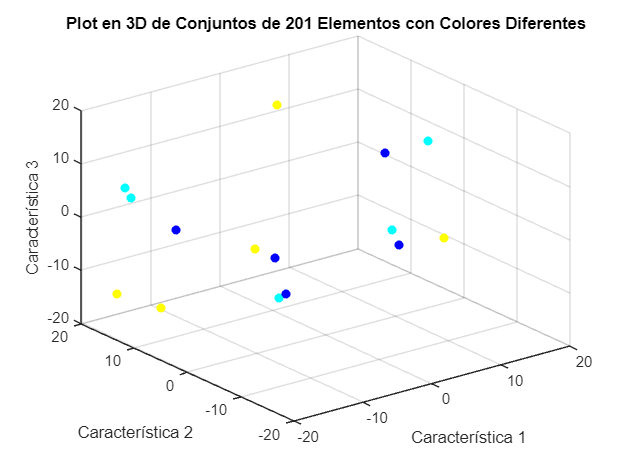

% Specify the file name
filename = 'vector_audios.csv';

% Write the table to the CSV file
writematrix(audios, filename);

% Supongamos que tu matriz de características se llama 'audios' y tiene las características en las columnas
% Ajusta 'audios' según el nombre real de tu matriz

% Crear una figura
figure;

% Número de conjuntos de 201 elementos
numSets = size(audios, 1) / 201;

% Colores para cada conjunto
colors = jet(numSets);

% Iterar sobre cada conjunto de 201 elementos
for i = 1:numSets
    startIndex = (i - 1) * 201 + 1;
    endIndex = i * 201;
    
    % Plotear los puntos del conjunto actual en 3D con un color diferente
    scatter3(audios(startIndex:endIndex, 1), audios(startIndex:endIndex, 2), audios(startIndex:endIndex, 3), 'filled', 'MarkerFaceColor', colors(i, :));
    hold on;  % Mantener el gráfico actual para superponer los conjuntos
end

% Etiquetas y título
xlabel('Característica 1');
ylabel('Característica 2');
zlabel('Característica 3');
title('Plot en 3D de Conjuntos de 201 Elementos con Colores Diferentes');

% Mostrar cuadrícula
grid on;

function reducedFeatures = normalizeAndReduceDimension(mfcc,min_mfccs,centroids,min_centroid,ratios,min_hr,entropies,min_entropy, targetLength)
    mfcc_matrix = zeros([201,min_mfccs]);
    ratios_matrix = zeros([201,min_hr]);
    centroids_matrix = zeros([201,min_centroid]);
    entropies_matrix = zeros([201,min_entropy]);
    for i=1:201
        mfcc_matrix(i,:) = mfcc(1:min_mfccs);
        centroid = centroids{i};
        centroids_matrix(i,:) = centroid(1:min_centroid);
        ratio = ratios{i};
        ratios_matrix(i,:) = ratio(1:min_hr);
        entropy = entropies{i};
        entropies_matrix(i,:) = entropy(1:min_entropy);
    end
    features = horzcat(mfcc_matrix,centroids_matrix,ratios_matrix,entropies_matrix);
    % Normalizar los datos
    normalizedFeatures = zscore(features);

    % Reducir la dimensión utilizando PCA
    coeff = pca(normalizedFeatures);
    reducedFeatures = normalizedFeatures * coeff(:,:);
    % Ajustar la longitud del vector de características a la deseada
    if size(reducedFeatures, 2) < targetLength
        % Si es más corto, rellenar con ceros
        reducedFeatures = horzcat(reducedFeatures,zeros([201,targetLength-size(reducedFeatures,2)]));
    else
        % Si es más largo, truncar
        reducedFeatures = reducedFeatures(:, 1:targetLength);
    end
end
